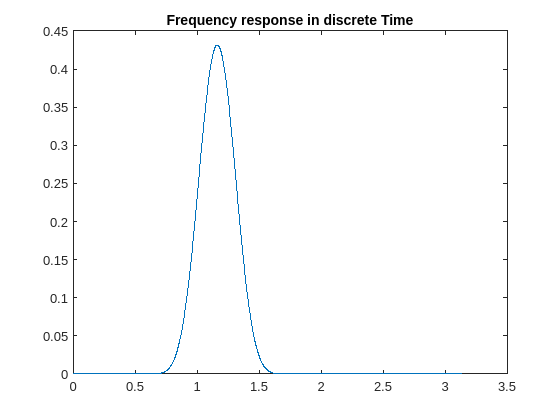

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%this file creates the FIR filter for the lab and defines the coefficients


%sets the time domain frequencies. In radians per second
Sampling_Frequency = 2*pi*16.2*10^3;
Center_Frequency = 2*pi*3*10^3;

%sets the band radius(half the bandwidth and the distance to the 
%upper and lower cutoff frequencies
%we set it to be 250 hertz, or its equivalent angular frequency
Band_Radius = 2*pi*200;

%sets the lower and upper cutoff frequencies
Cutoff_Lower = Center_Frequency - Band_Radius;
Cutoff_Upper = Center_Frequency + Band_Radius;

%End of continuous time frequencies
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Discrete Time frequencies
%sets the discrete time equivalents of those frequencies
Discrete_Center_Frequency = 2*pi*Center_Frequency/Sampling_Frequency;
Discrete_Cutoff_Lower = 2*pi*Cutoff_Lower/Sampling_Frequency;
Discrete_Cutoff_Upper = 2*pi*Cutoff_Upper/Sampling_Frequency;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%sets the length of the Filter, and creates the array of the coefficients
%Length of Filter, N
N = 50;
%helper variable M, one less than N
M = N - 1;
%creates the H_desired array
H_desired = zeros(N,1);

%iterates through and sets the array with the coefficients of the desired
%design
for i = 1:N
    H_desired(i,1) = (Discrete_Cutoff_Upper/pi)*sinc((Discrete_Cutoff_Upper/pi)*(i-M/2)) - (Discrete_Cutoff_Lower/pi)*sinc((Discrete_Cutoff_Lower/pi)*(i-M/2));
end

%gets the corresponding Chebyshev Polynomial for the window
ChebyshevWindow = chebwin(N);

%gets the corresponding Blackman Polynomial for the window
BlackmanWindow = blackman(N);

%actual filter with the chebychev polynomial
H_chebychev_realized = zeros(N,1);

%iterates through and multiplies each element of the sinc function low pass
%filter and the Chebyshev Window and 
for i = 1:N
    H_chebychev_realized(i) = H_desired(i)*ChebyshevWindow(i);
end

%does the same thing for the alternative blackman window
H_blackman_realized = zeros(N,1);
for i = 1:N
    H_blackman_realized(i) = H_desired(i)*BlackmanWindow(i);
end

frequency_response_points = 2000;

%gets the frequency response for the unwindowed version
[h_0,w_0] = freqz(H_desired,1,frequency_response_points);

%gets the frequency response for the chebychebv windowed version
[h_1,w_1] = freqz(H_chebychev_realized,1,frequency_response_points);

%gets the frequency response for the 
[h_2,w_2] = freqz(H_blackman_realized,1,frequency_response_points);

plot(w_1,abs(h_1));
title("Frequency response in discrete Time");

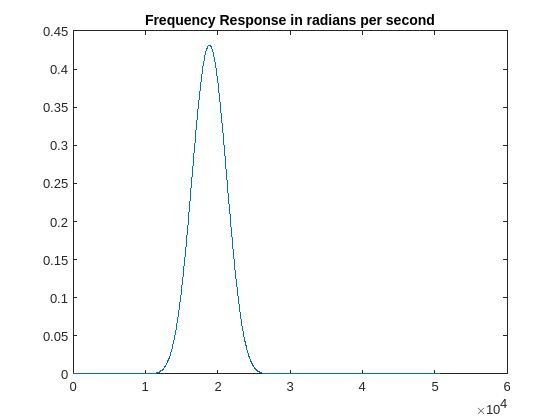



plot(w_1*Sampling_Frequency/(2*pi),abs(h_1));
title("Frequency Response in radians per second");

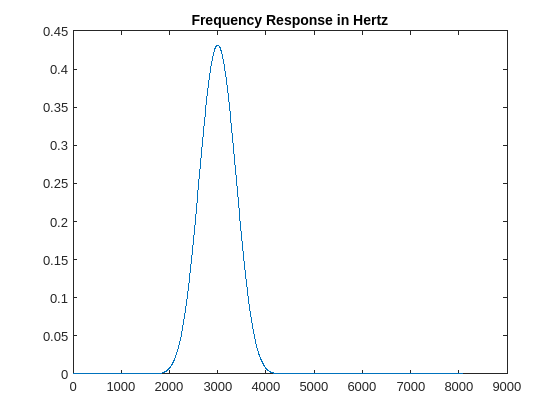


plot((w_1*Sampling_Frequency/(2*pi))/(2*pi),abs(h_1));
title("Frequency Response in Hertz");

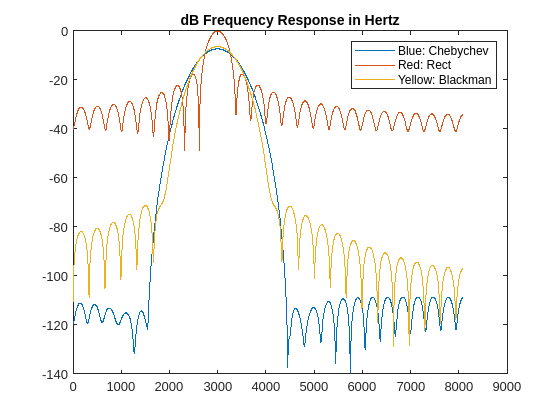



plot((w_1*Sampling_Frequency/(2*pi))/(2*pi),20*log10(abs(h_1)));

title("dB Frequency Response in Hertz");
hold on;
plot((w_1*Sampling_Frequency/(2*pi))/(2*pi),20*log10(abs(h_0)));
plot((w_1*Sampling_Frequency/(2*pi))/(2*pi),20*log10(abs(h_2)));
legend('Blue: Chebychev', 'Red: Rect',  'Yellow: Blackman');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
